#  Patrones 04 - Red Neuronal

Script for creating and training a deep learning network with the following properties:

Run this script to create the network layers, import training and validation data, and train the network. The network layers are stored in the workspace variable `layers`. The trained network is stored in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 27-Aug-2020 13:57:50

## Load Initial Parameters

Load parameters for network initialization. For transfer learning, the network initialization parameters are the parameters of the initial pretrained network.

% trainingSetup = load("trainingSetup_2020_08_27__13_57_44.mat");

% load datosDimensiones
resolucion = 128;
profundidad = 1;

## Import Data

Import training and validation data.

imdsTrain = imageDatastore("imgPatronesMulti","IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain, imdsValidation] = splitEachLabel(imdsTrain,0.6);

## Augmentation Settings

% imageAugmenter = imageDataAugmenter(...
%     "RandXReflection",false,...
%     "RandYReflection",false);
% 
% % Resize the images to match the network input layer.
% augimdsTrain = augmentedImageDatastore([resolucion resolucion profundidad],imdsTrain,"DataAugmentation",imageAugmenter);
% augimdsValidation = augmentedImageDatastore([resolucion resolucion profundidad],imdsValidation);

## Set Training Options

Specify options to use when training.

opts = trainingOptions("sgdm",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",0.01,...
    "MaxEpochs",3,...
    "Shuffle","every-epoch",...    
    "ValidationFrequency",45,...
    "Plots","training-progress",...
    "ValidationData",imdsValidation,...
    "Verbose",false);



% inicio = 8; 

## Create Array of Layers

layers = [

    imageInputLayer([resolucion resolucion profundidad], "Normalization", "rescale-zero-one")

    convolution2dLayer([3 3],8,"Padding","same")
    maxPooling2dLayer([2 2],"Padding","same","Stride",[2 2])
    reluLayer;
    batchNormalizationLayer
    
%     convolution2dLayer([3 3],16,"Padding","same")
%     maxPooling2dLayer([2 2],"Padding","same","Stride",[2 2])
%     reluLayer;
%     batchNormalizationLayer
% 
%     convolution2dLayer([3 3],32,"Padding","same")
%     maxPooling2dLayer([2 2],"Padding","same","Stride",[2 2])
%     reluLayer;
%     batchNormalizationLayer

%     convolution2dLayer([3 3],128,"Padding","same")
%     maxPooling2dLayer([2 2],"Padding","same","Stride",[2 2])
%     reluLayer
%     batchNormalizationLayer

%     fullyConnectedLayer(32)
%     reluLayer
%     batchNormalizationLayer

    fullyConnectedLayer(6)
    softmaxLayer
    classificationLayer];

## Train Network

Train the network using the specified options and training data.

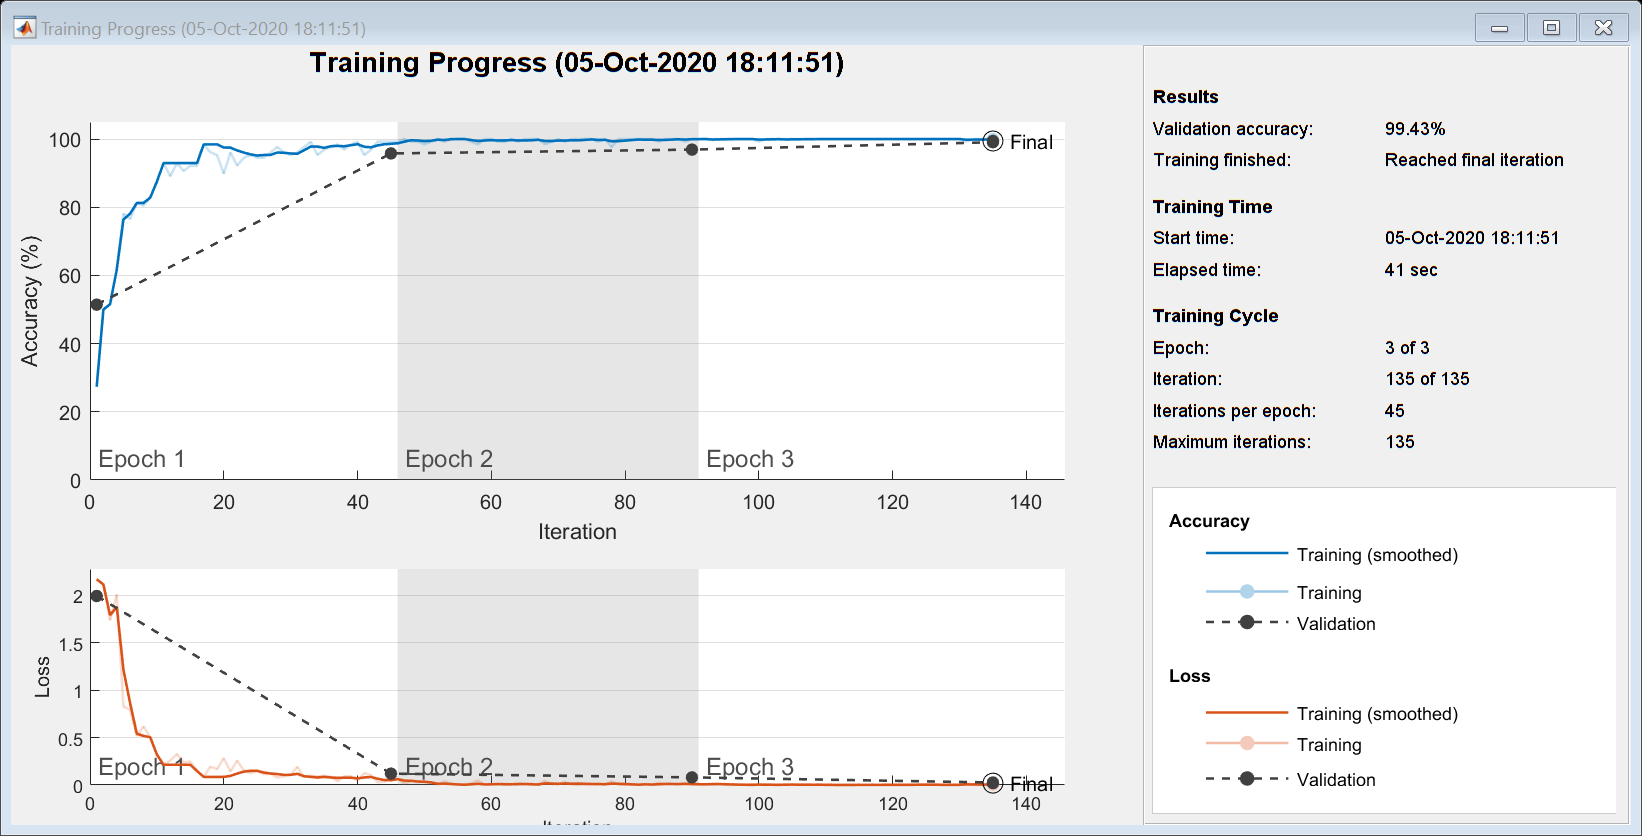

[net, traininfo] = trainNetwork(imdsTrain,layers,opts);

## Save Results

save resultados net imdsTrain imdsValidation layers opts